## Setup

set(groot,'defaultAxesFontSize', 20);
set(groot,'defaultFigureColor', [1, 1, 1]);
set(groot,'defaultLineLineWidth',4);

clc; clear; close all;

## Parameters

% Constants
eps_0 = 8.8541878128e-12; % F m-1 % permittivity of free space (vacuum permittivity)
densitywater = 1000; % kg m-3
waterspecificheat = 4184; % J kg-1 K-1

% Conversions
Vperm_to_kVpercm = 1e-5;
Jperm3_to_mJpercm3 = 1e-3;
s_to_us = 1e6;
ul_to_m3 = 1e-9;
min_to_s = 1/60;
kVpercm_to_Vperm = 1/Vperm_to_kVpercm;
MVpercm_to_Vperm = 1e6/1e-2;
Vperm_to_MVpercm = 1/MVpercm_to_Vperm;

% Thresholds
criticalMembraneVoltage = 1;
temp_increase_threshold = 1; 

% Channel / Liquid
c_w = 140e-6; % m
c_h = 70e-6; % m
z_l = 200e-6; % m
eps_l = 80; % water dielectric constant
sigma_l_mSpercm = 1.3;
sigma_l = sigma_l_mSpercm*100/1000; % S/m
sigma_a = 0.2; % S*m-1 By Timoshkin et al 2006
rho_l = 1/sigma_l;
rho_a = 1/sigma_a;
csa_l = c_w * c_h;
v_l = csa_l * z_l;
m_l = v_l * densitywater;

% Flow
Qf = 450; % ul / min
Qf = Qf * ul_to_m3 * min_to_s; % m^3/s

% Cell Properties
cell_diameter = 30e-6;
cell_radius = cell_diameter/2;
cell_diameter_low = 10e-6; % diameter of the cell;
cell_radius_low = cell_diameter_low/2;
cell_diameter_high = 40e-6; % diameter of the cell;
cell_radius_high = cell_diameter_high/2;
C_m = 1e-2; % F/m^2, capacitance of the membrane per unit area, Schwan Paper
% 10mF/m^2 for HEK (aka 0.01 or 1e-2 F/m2) http://dx.doi.org/10.1016/j.bpj.2017.08.006
% 90 uF/cm^2 OR 90e-6/(1e-2)^2 or 0.9 F/m2
% 2e-2 S/m, OR 2 uF/cm2 OR 2e-6 F / (1e-2 m)^2 (10.1038/sdata.2017.15)
theta = 0;
G_m = 100; % S/m^2 Schwan Paper
% 187 S/m2 for HEK http://dx.doi.org/10.1016/j.bpj.2017.08.006 
G_s = 1e-9; % S/m^2
threshold_EField_IRE = 10; % kV/cm

% Dielectric
dielectrics = {
    "TiO_2",    80,    1.6
    "HfO_2",    25,     6.7
    "SiO_2",    3.6,    10
    "Si_3N_4",  7.5,    10
    "Al_20_3",  7.8,    8
    "PDMS",     2.6,    14
};

Name = [dielectrics{:,1}]';
k = [dielectrics{:,2}]';
Strength = [dielectrics{:,3}]';

dielectric = Name(1);
eps_d = k(Name == dielectric);
k_d_breakdown = Strength(Name == dielectric) * MVpercm_to_Vperm; % Table Strength values are in MV/cm

z_d = 143e-9; % m (DIELECTRIC THICKNESS)

% Voltage
U_0 = 179; % (STIMULATION AMPLITUDE)

duty_cycle = 100 ; % (Percent)

inspect_frequency = 210e3; % (KHZ)

## Calculate Impulse Response

% I V Timoshkin et al 2006 J. Phys. D: Appl. Phys. 39 596 (doi:10.1088/0022-3727/39/3/026)
tau_f = (eps_l/eps_d + z_l/(2*z_d)) * ((eps_0*eps_d)/sigma_l); % Equation (8)
E_L = U_0 * (z_l + 2*(eps_l/eps_d)*z_d)^-1; % Equation (7)
% E_0 = E_L * exp(-t/tau_f); % Equation (6) (Not needed)

% Adapted from Equation (6) which is the time-domain impulse response
% Below, sysEField is the impulse response of the electric field in the
% dual-dielectric setup shown in Timoshkin et al 2006 Figure 1.
sysEField = tf([E_L/U_0 0], [1, 1/tau_f]); 

## Calculate the Bode Plot of the Electric Field in the Channel

fin = logspace(1,9,1000);
fin = [fin inspect_frequency];
win = fin*(2*pi);
[mag, phase, wout] = bode(sysEField, win);
fout = wout/(2*pi);

EField_mag_out = squeeze(mag).*U_0;
phase = squeeze(phase);

## Calculate Voltage Drop Across the Dielectric

% amplitude of difference of sines 
% with phase shift on second sine wave (< 90 deg)
% A_3 = sqrt((A_1 - A_2*cos(phi))^2 + (A_2*sin(phi))^2)

% Vdrop in channel:
V_d = EField_mag_out*z_l;
phi = phase/180*pi;

Vdiff = sqrt((U_0 - V_d .* cos(phi)).^2 + (V_d.*sin(phi)).^2);

EField_dielectric = Vdiff/(2*z_d);

## Calculate the Voltage Induced in the Cell Membrane

% C Grosse and H P Schwan 1992 Biophys J. 1632
% (10.1016/s0006-3495(92)81740-x)
% Equation (1), adapted with theta = 0 and rho_i == rho_a == rho. Other equations 10, 11, and 12 can be used
dU_mag_1 = @(E, R, wout, C_m, rho_i, rho_a, G_s, G_m) abs((3/2 * E * R)./(1+1i*wout*R*C_m*(rho_i + rho_a/2))); % Equation (1)

rho_i = rho_a;
dU_low = dU_mag_1(EField_mag_out, cell_radius_low, wout, C_m, rho_i, rho_l, G_s, G_m);
dU_cell = dU_mag_1(EField_mag_out, cell_radius, wout, C_m, rho_i, rho_l, G_s, G_m);
dU_high = dU_mag_1(EField_mag_out, cell_radius_high, wout, C_m, rho_i, rho_l, G_s, G_m);

## Calculate the Temperature Increase In the Channel

resistance_l = rho_l * z_l/csa_l; % ohms
power_l = ((duty_cycle/100)*EField_mag_out/(2*sqrt(2)) * z_l).^2 / resistance_l; % W or J/s
t_traverse_l = z_l/(Qf/csa_l); % s
energy_l = power_l*t_traverse_l; % J (delivered to a unit of water traversing electrodes at average velocity)
temp_increase = energy_l/waterspecificheat/m_l; % deg C


## Calculate the Threshold E-Field

% ML Yarmoush et al 2014 Annu. Rev. Biomed. Eng. 16:295-320
% (10.1146/annurev-bioeng-071813-104622)
% Data Extracted from Figure 3a with webplotdigitizer
data = [3.9810717055349776e-8, 221221.22793001338
        4.836231063747682e-8, 164066.88645104118
        6.228252301642084e-8, 112917.1224201178
        8.670181100746345e-8, 65281.86289344937
        1.4662133959873385e-7, 36352.38651155641
        2.786572985617775e-7, 19257.77084002022
        4.899376841992004e-7, 11411.906461488581
        8.783386058472576e-7, 7470.437249217064
        0.0000014286622765964932, 5678.541080728857
        0.00000317254981970173, 4261.871042689962
        0.000007468604063867926, 3119.8246598925766
        0.000017243273563482123, 2554.5613106713486
        0.00003829116603065697, 2226.1002982253754
        0.0001304646813114124, 1868.0539626753593
        0.00035886373877923214, 1668.57172567252
        0.0009680894625777776, 1509.0838148194541
        0.0026628831690025338, 1314.7949064436546
        0.006517552032847415, 1174.5165883243096
        0.022206436550279086, 1075.3298029779562
        0.04836231063747681, 1022.3874999644569
        0.12306678212252006, 971.9154223068523
];
% (ln(datax), ln(datay)) fit with double exponential and converted to
% linear scale again:
%a = 0.0045; b = -0.4048; c = 6.7272; d = -0.0097; % fit to lower bound of IRE region
%a = 0.0212; b = -0.3065; c = 5.6391; d = -0.0072; % fit to lower bound of RE region
%a = 0.0021; b = -0.6738; c = 8.6799; d = -0.0284; % fit to lower bound of Thermal IRE region
half_stim_period = 1./fin/2;

% fit to lower bound of IRE region
a = 0.0045; b = -0.4048; c = 6.7272; d = -0.0097; 
threshold_EField_Vpercm = exp(a*half_stim_period.^b + c*half_stim_period.^d);
threshold_EField_IRE = threshold_EField_Vpercm'/1000;

% fit to lower bound of RE region
a = 0.0212; b = -0.3065; c = 5.6391; d = -0.0072; 
threshold_EField_Vpercm = exp(a*half_stim_period.^b + c*half_stim_period.^d);
threshold_EField_RE = threshold_EField_Vpercm'/1000;

% fit to lower bound of Thermal IRE region
a = 0.0021; b = -0.6738; c = 8.6799; d = -0.0284; 
threshold_EField_Vpercm = exp(a*half_stim_period.^b + c*half_stim_period.^d);
threshold_EField_TRE = threshold_EField_Vpercm'/1000;

%threshold_EField should be a function of frequency

## Plot

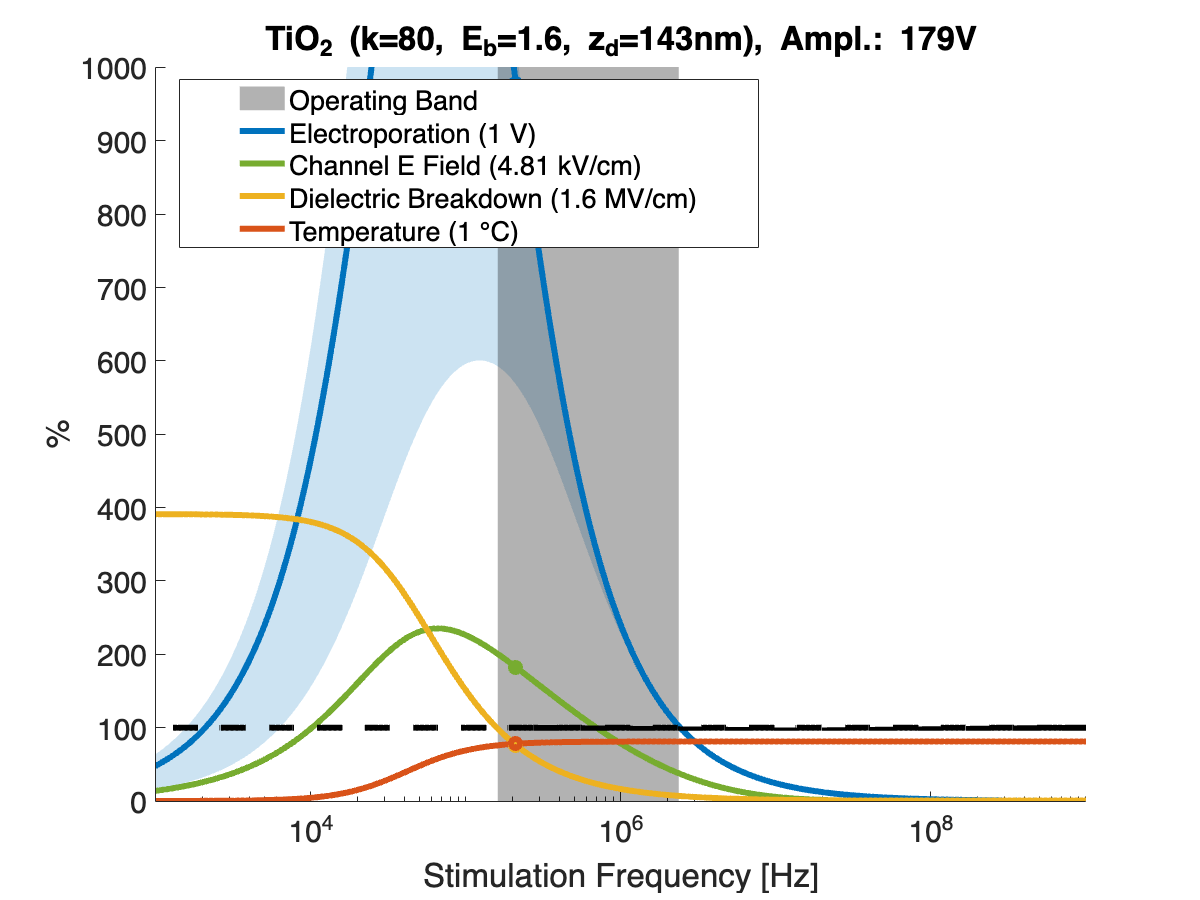

figure; hold on;
% Shade showing the lower bound and upper bound of membrane potential
% induced in cells of various sizes
fill([fout(1:end-1)' fliplr(fout(1:end-1)')], ...
    100*[dU_low(1:end-1)'/criticalMembraneVoltage, fliplr(dU_high(1:end-1)'/criticalMembraneVoltage)], ...
    [0 0.4470 0.7410], ...
    'FaceAlpha',0.2, ...
    'LineStyle', 'none' ...
);

ideal_band = dU_low/criticalMembraneVoltage > 1 & EField_dielectric/k_d_breakdown < 1 & temp_increase/temp_increase_threshold < 1;
ideal_band_width = max(fout(ideal_band)) - min(fout(ideal_band));
ymax = 100 * max([dU_low'/criticalMembraneVoltage, EField_dielectric'/k_d_breakdown, temp_increase'/temp_increase_threshold]);
rectheight = 10*10^ceil(log10(ymax));
patchx = [0 1 1 0].*ideal_band_width + min(fout(ideal_band));
patchy = [0 0 1 1].*rectheight + 0;
if ~isempty(ideal_band_width)
    patch(patchx, patchy, 'k', 'FaceAlpha', 0.3, 'LineStyle', 'none');
end

plot(fout(1:end-1), dU_cell(1:end-1)/criticalMembraneVoltage * 100); % percentage of membrane voltage
%plot(fout, dU_high/criticalMembraneVoltage * 100); % percentage of membrane voltage
plot(fout(1:end-1), EField_mag_out(1:end-1)*Vperm_to_kVpercm./threshold_EField_IRE(1:end-1) * 100, 'Color', [0.4660 0.6740 0.1880])
plot(fout(1:end-1), EField_dielectric(1:end-1)/k_d_breakdown * 100, 'Color', [0.9290 0.6940 0.1250]); % percentage of dielectric strength
plot(fout(1:end-1), temp_increase(1:end-1)/temp_increase_threshold * 100, 'Color', [0.8500 0.3250 0.0980]);

% Plot points at the inspection frequency
plot(fout(end), dU_cell(end)/criticalMembraneVoltage * 100, 'o', 'Color', [0 0.4470 0.7410]); % percentage of membrane voltage
plot(fout(end), EField_mag_out(end)*Vperm_to_kVpercm./threshold_EField_IRE(end) * 100, 'o', 'Color', [0.4660 0.6740 0.1880])
plot(fout(end), EField_dielectric(end)/k_d_breakdown * 100, 'o', 'Color', [0.9290 0.6940 0.1250]); % percentage of dielectric strength
plot(fout(end), temp_increase(end)/temp_increase_threshold * 100, 'o', 'Color', [0.8500 0.3250 0.0980]);


plot(fout, fout*0 + 100, 'k--');
set(gca, 'XScale', 'log');
xlabel('Stimulation Frequency [Hz]');
ylabel('%');
if sum(ideal_band) > 0
    legend({'',...
        'Operating Band', ...
        sprintf('Electroporation (%.3g V)', criticalMembraneVoltage), ...
        sprintf('Channel E Field (%.3g kV/cm)', threshold_EField_IRE(end)), ...
        sprintf('Dielectric Breakdown (%.3g MV/cm)', k_d_breakdown*Vperm_to_MVpercm), ...
        sprintf(['Temperature (%.3g ' char(176) 'C)'], temp_increase_threshold) ...
    });
else
    legend({'',...
        sprintf('Electroporation (%.3g V)', criticalMembraneVoltage), ...
        sprintf('Channel E Field (%.3g kV/cm)', threshold_EField_IRE(end)), ...
        sprintf('Dielectric Breakdown (%.3g MV/cm)', k_d_breakdown*Vperm_to_MVpercm), ...
        sprintf(['Temperature (%.3g ' char(176) 'C)'], temp_increase_threshold) ...
    });
end
xlim([1e3, 1e9]);
ylim([0, 1000]);

title(sprintf('%s (k=%.3g, E_{b}=%.3g, z_{d}=%.3gnm), Ampl.: %.3gV', dielectric, eps_d, k_d_breakdown*Vperm_to_MVpercm, z_d*1e9, U_0));

legend("Position", [0.14972,0.72617,0.48214,0.18452])

if sum(ideal_band) > 0
    %max(dU_low(ideal_band))
end

set(gcf,'position',[0,0,800,600]);



% 
% figure; hold on;
% plot(fout(1:end-1), phase(1:end-1), 'Color', [0.9290 0.6940 0.1250]);
% plot(fout(end), phase(end), 'o', 'Color', [0.9290 0.6940 0.1250]); % percentage of dielectric strength
% set(gca, 'XScale', 'log');
% set(gcf,'position',[0,0,800,600]);
% ylabel('Phase');
% xlim([1e4 1e8])
% xlabel('Stimulation Frequency [Hz]');

fprintf(1, 'Electric Field: %.3g kV/cm', EField_mag_out(end)*Vperm_to_kVpercm);

Electric Field: 8.77 kV/cm

fprintf(1, 'Induced V_m: %.3g V', dU_cell(end));

Induced V_m: 9.78 V

fprintf(1, 'Dielectric Field: %.3g MV/cm', EField_dielectric(end)*Vperm_to_MVpercm);

Dielectric Field: 1.22 MV/cm

fprintf(1, 'Temperature Increase: %.3g C', temp_increase(end));

Temperature Increase: 0.78 C

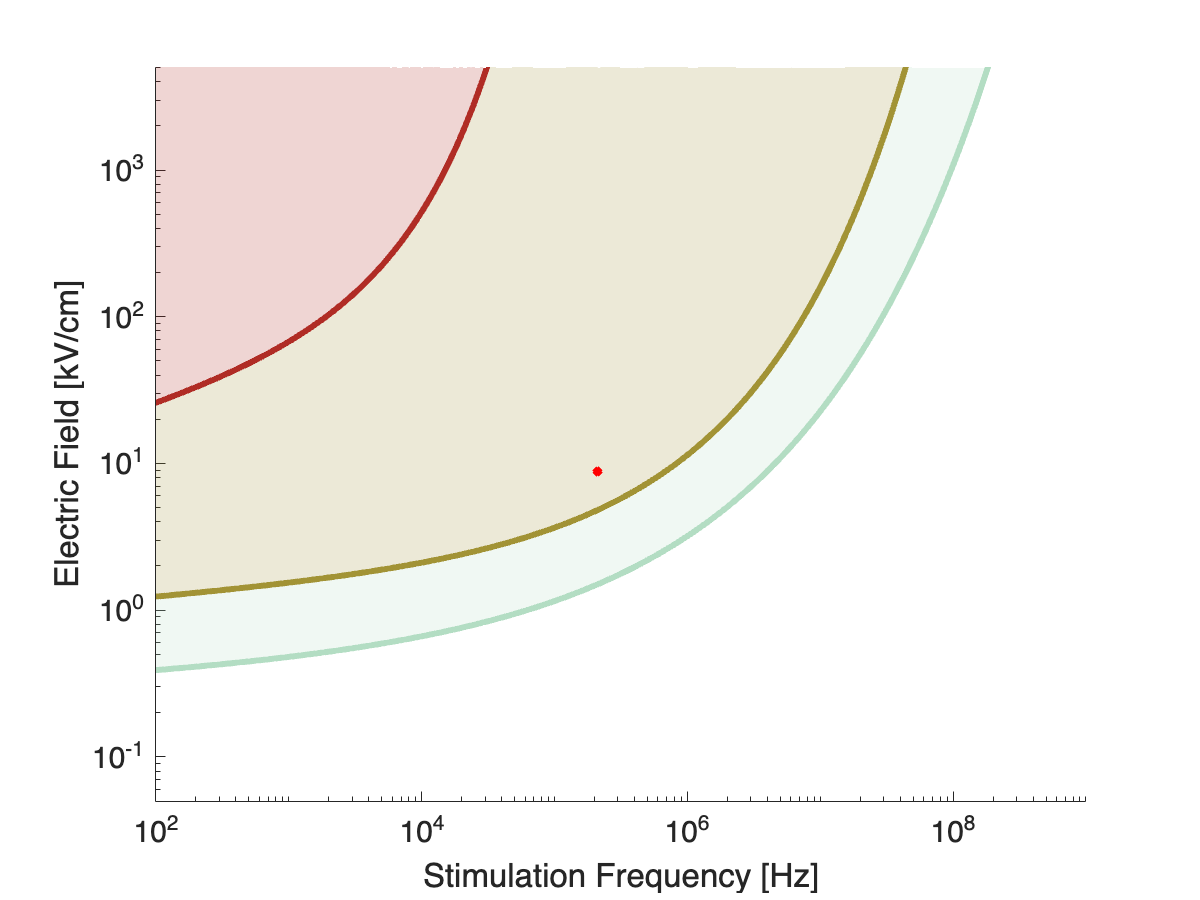



% figure; hold on;
% % Shade showing the lower bound and upper bound of membrane potential
% % induced in cells of various sizes
% REVec = EField_mag_out(1:end-1)*Vperm_to_kVpercm./threshold_EField_RE(1:end-1) * 100;
% IREVec = EField_mag_out(1:end-1)*Vperm_to_kVpercm./threshold_EField_IRE(1:end-1) * 100;
% TREVec = EField_mag_out(1:end-1)*Vperm_to_kVpercm./threshold_EField_TRE(1:end-1) * 100;
% fill([fout(1:end-1)' fliplr(fout(1:end-1)')], ...
%     [REVec', fliplr(IREVec')], ...
%     [179 221 195]/255, ...
%     'FaceAlpha',0.2, ...
%     'LineStyle', 'none' ...
% );
% fill([fout(1:end-1)' fliplr(fout(1:end-1)')], ...
%     [IREVec', fliplr(TREVec')], ...
%     [162 147 53]/255, ...
%     'FaceAlpha',0.2, ...
%     'LineStyle', 'none' ...
% );
% fill([fout(1:end-1)' fliplr(fout(1:end-1)')], ...
%     [TREVec', fliplr(0*TREVec')], ...
%     [176 44 37]/255, ...
%     'FaceAlpha',0.2, ...
%     'LineStyle', 'none' ...
% );
% plot(fout(1:end-1), REVec, 'Color', [179 221 195]/255)
% plot(fout(1:end-1), IREVec, 'Color', [162 147 53]/255)
% plot(fout(1:end-1), TREVec, 'Color', [176 44 37]/255)
% plot(fout, fout*0 + 100, 'k--');
% xlim([1e3, 1e9]);
% ylim([0, 1000]);
% set(gca, 'XScale', 'log');

color_RE = [179 221 195]/255;
color_IRE = [162 147 53]/255;
color_TRE = [176 44 37]/255;


figure; hold on;
display_threshold_EField_RE = threshold_EField_RE; 
display_threshold_EField_RE(display_threshold_EField_RE > 1e10) = 1e10;
display_threshold_EField_IRE = threshold_EField_IRE;
display_threshold_EField_IRE(display_threshold_EField_IRE > 1e10) = 1e10;
display_threshold_EField_TRE = threshold_EField_TRE;
display_threshold_EField_TRE(display_threshold_EField_TRE > 1e10) = 1e10;

fill([fout(1:end-1)' fliplr(fout(1:end-1)')], ...
    [display_threshold_EField_RE(1:end-1)', fliplr(display_threshold_EField_IRE(1:end-1)')], ...
    color_RE, ...
    'FaceAlpha',0.2, ...
    'LineStyle', 'none' ...
);
fill([fout(1:end-1)' fliplr(fout(1:end-1)')], ...
    [display_threshold_EField_IRE(1:end-1)', fliplr(display_threshold_EField_TRE(1:end-1)')], ...
    color_IRE, ...
    'FaceAlpha',0.2, ...
    'LineStyle', 'none' ...
);
fill([fout(1:end-1)' fliplr(fout(1:end-1)')], ...
    [display_threshold_EField_TRE(1:end-1)', fliplr(1e10 + 0*display_threshold_EField_TRE(1:end-1)')], ...
    color_TRE, ...
    'FaceAlpha',0.2, ...
    'LineStyle', 'none' ...
);

title('Electric Field Plot from Yarmush et al 2014');
plot(fout(1:end-1), display_threshold_EField_RE(1:end-1), 'Color', color_RE);
plot(fout(1:end-1), display_threshold_EField_IRE(1:end-1), 'Color', color_IRE);
plot(fout(1:end-1), display_threshold_EField_TRE(1:end-1), 'Color', color_TRE);
plot(fout(end), EField_mag_out(end)*Vperm_to_kVpercm    , 'rx');
set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');
xlim([1e2, 1e9]);
ylim([5e-2, 5e3]);
xlabel('Stimulation Frequency [Hz]');
ylabel('Electric Field [kV/cm]');

set(gcf,'position',[0,0,800,600]);